# What is the data ?

We have some data but it is becoming more and more apparent that we have no idea what it is. 

load 'quad_copter_models.mat';
ol_data = load('dati_id_ol_scalati.mat');

time   = ol_data.t;
data_u = ol_data.u;

The values of `ol_data.y` are between -104 and 90. since it represents a rotation per second it is too high to be a value in radians. We have to assume that it is in degrees. Our model however works in radians (I think ?) so we need to convert to radians.

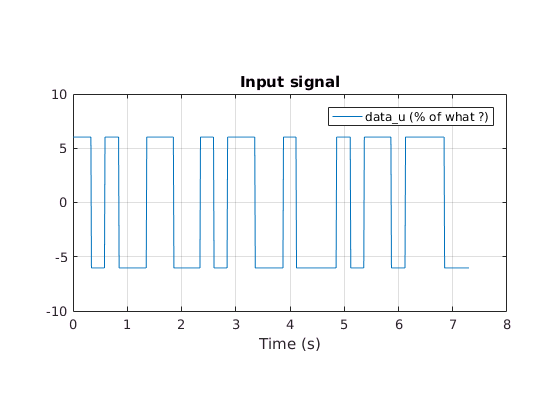

q_dot_real   = deg2rad(ol_data.yi);   
q_dot_sim_dO = lsim(PitchRateModel        , data_u, time); % Assumes u is dOmega
q_dot_sim_dM = lsim(PitchRateModel * Mixer, data_u, time); % Assumes u is dM

figure()
    plot(time, data_u); legend('data\_u (% of what ?)'); % ylim([-1.5, 1.5]); 
    xlabel('Time (s)'); title('Input signal')
    pbaspect([1 .5 1]);

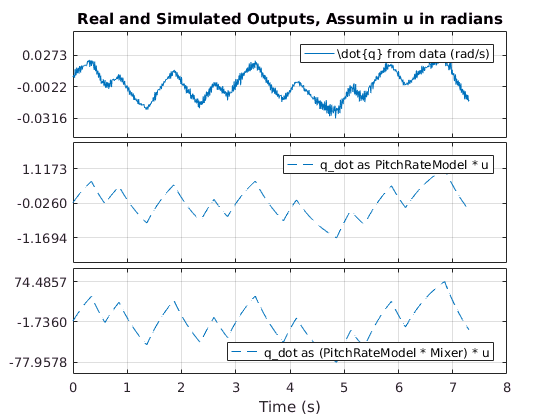

        
figure()
    subplot(3, 1, 1);
        plot(time, q_dot_real); legend('\dot{q} from data (rad/s)'); % ylim([-.7*pi, .7*pi]);
        title('Real and Simulated Outputs, Assumin u in radians');
    subplot 312;
        plot(time, q_dot_sim_dO, '--'); legend('q\_dot as PitchRateModel * u'); % ylim([-.1*pi, .1*pi]);
    subplot 313;
        plot(time, q_dot_sim_dM, '--'); legend('q\_dot as (PitchRateModel * Mixer) * u', 'Location', 'southEast'); 
        xlabel('Time (s)'); % ylim([-5*pi, 5*pi]);
condense_subplots('tight', true);       

From these plots we cannot conclude anything. If we assume that `u` was collected before the `Mixer `the simulated signal is ~6 times bigger than the measured signal. If we assume that `u` was collected after the Mixer then the graph is ~7 smaller than the expected output. The distance between the tow errors does not allow us to favour one scenario or the other. 

## Assume that the data is take before the mixer

Since the input is a percentage we want to reverse engineer the reference value.

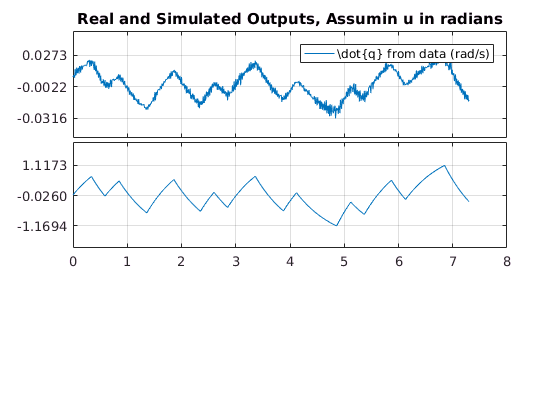

figure()
    subplot(3, 1, 1);
        plot(time, q_dot_real); legend('\dot{q} from data (rad/s)'); % ylim([-.7*pi, .7*pi]);
        title('Real and Simulated Outputs, Assumin u in radians');
    subplot 312;
        plot(time, q_dot_sim_dO)
condense_subplots('tight', true);      